# Columns and Diagonals of Different Sizes

Examine how `spdiags` creates diagonals when the columns of the input matrix are longer than the diagonals they are replacing.

Create a 6-by-7 matrix of the numbers 1 through 6.

Bin = repmat((1:6)',[1 7])

Use `spdiags` to create a square 6-by-6 matrix with several of the columns of `Bin` as diagonals. Because some of the diagonals only have one or two elements, there is a mismatch in sizes between the columns in `Bin` and diagonals in `A`.

d = [-4 -2 -1 0 3 4 5];
A = spdiags(Bin,d,6,6);
full(A)

Each of the columns in `Bin` has six elements, but only the main diagonal in `A` has six elements. Therefore, all the other diagonals in `A` truncate the elements in the columns of `Bin` so that they fit on the selected diagonals:

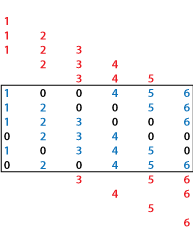

The way `spdiags` truncates the diagonals depends on the size of `m`-by-`n` matrix `A`. When $m\ge n$, the behavior is as pictured above:

- Diagonals *below* the main diagonal take elements from the *tops* of the columns first.

- Diagonals *above* the main diagonal take elements from the *bottoms* of columns first.

This behavior reverses when $m<n$:

A = spdiags(Bin,d,5,6);
full(A)

- Diagonals *above* the main diagonal take elements from the *tops* of the columns first.

- Diagonals *below* the main diagonal take elements from the *bottoms* of columns first.

*Copyright 2019 The MathWorks, Inc.*